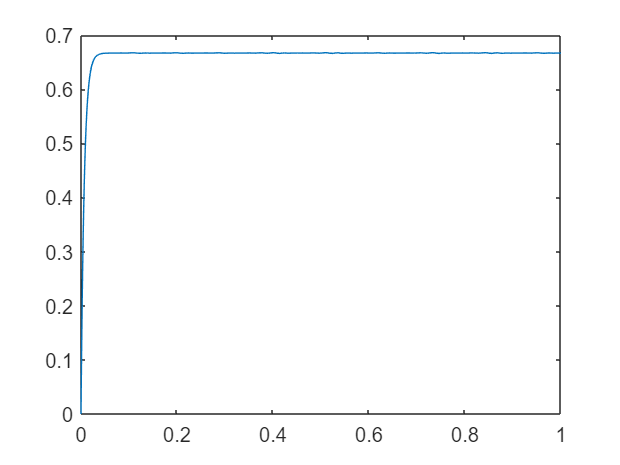

clear
clc

% all possible scans the robot can make
% input format: [xi, I, wij, xj]  
% bac = input('back') 
% backleft = input('backleft') 
% left = input('left') 
% frontleft = input('frontleft') 
% front = input('front')
% frontright = input('frontright')
% right = input('right')
% backright = input('backright')

bac = [0, -100, 1, 0];
backleft = [0, -100, 2, 0];
left = [0, -100, 1, 0];
frontleft = [0, -100, 2, 0];
front = [0, 100, 1, 0];
frontright = [0, 100, 2, 0];
right = [0, 100, 1, 0];
backright = [0, -100, 2, 0];

scan = [bac; backleft; left; frontleft; front; frontright; right; backright];

%calculate sum of weights
%weight = bac(3)*bac(4) + backleft(3)*backleft(4) + left(3)*left(4) + frontleft(3)*frontleft(4) + front(3)*front(4) + frontright(3)*frontright(4) + right(3)*right(4) + backright(3)*backright(4);
weight = scan(1,3)*scan(1,4) + scan(2,3)*scan(2,4) + scan(3,3)*scan(3,4) + scan(4,3)*scan(4,4) + scan(5,3)*scan(5,4) + scan(6,3)*scan(6,4) + scan(7,3)*scan(7,4) + scan(8,3)*scan(8,4); 

%set variables
A = 50;
B = 1;
D = 1;

%eqn = @(t,x) ((-A*x) + (B-x)*(scan(1,2) + weight) - (1+x)*scan(1,2));
eqn = @(t,x) ((-A*x) + (B-x)*(0 + 100) - (1+x)*00);
[t,x] = ode45(eqn, [0:1], scan(1,1));
x;
plot(t,x)


% %solve dfq
% for i = 1:1:8
% eqn = @(t,x) ((-A*x) + (B-x)*(scan(i,2) + weight) - (1+x)*scan(i,2));
% [t,x] = ode45(eqn, [0:0.5:1], scan(i,1));
% scan(i,1) = x(3);
% end
% plot(t,x,'-')



%disp(scan)